# Open FrontHaul

Calculates the packet size from SCS, BW, FR

## Overall Approach

3GPP 38.101 has specified maximum transmision bandwidth configuration for each UE cahnnel and SCS provided in the below table. The resource block number shown is after removing the guard band form channel bandwidth and the maximum badnwidth considered is 100 MHz.

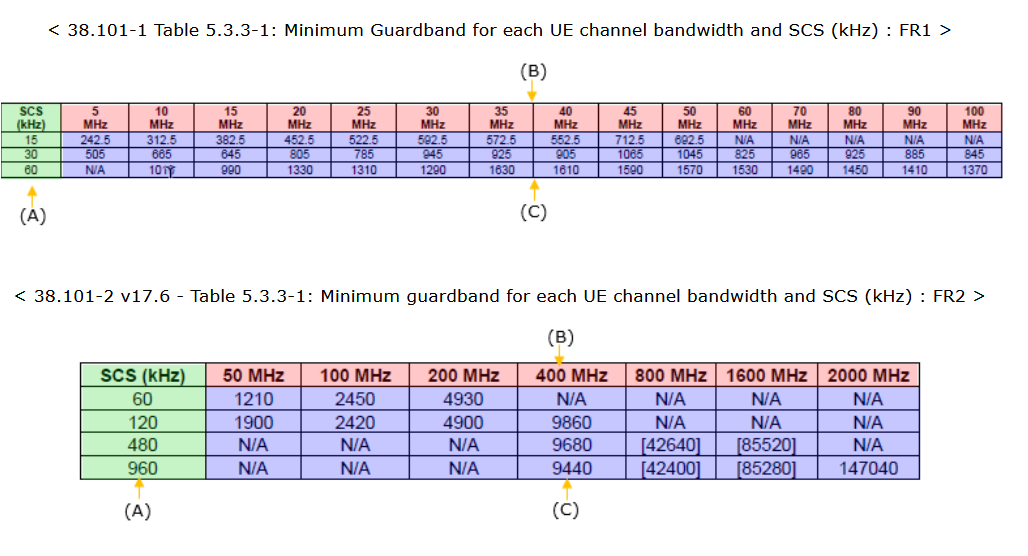

## Packet size O-FH [U-plane flow]

U-Plane traffic depends on the following features

% Define the SCS (Subcarrier Spacing) values in kHz
SCS_values = [15, 30, 60];

% Define the bandwidth values in MHz
bandwidth_values = [5, 10, 15, 20, 25, 30, 40, 50, 60, 70, 80, 90, 100];

% Define the data values from the table
data = [
    242.5, 312.5, 382.5, 452.5, 522.5, 592.5, 552.5, 692.5, NaN, NaN, NaN, NaN, NaN;
    505, 665, 645, 805, 785, 945, 905, 1045, 825, 965, 925, 885, 845;
    NaN, 1010, 990, 1330, 1310, 1290, 1610, 1570, 1530, 1490, 1450, 1410, 1370
];

% Create a MATLAB table
table_data = array2table(data, 'RowNames', string(SCS_values), 'VariableNames', string(bandwidth_values));

% Display the table
disp(table_data);

            5       10       15       20       25       30       40       50       60      70      80      90     100 
          _____    _____    _____    _____    _____    _____    _____    _____    ____    ____    ____    ____    ____

    15    242.5    312.5    382.5    452.5    522.5    592.5    552.5    692.5     NaN     NaN     NaN     NaN     NaN
    30      505      665      645      805      785      945      905     1045     825     965     925     885     845
    60      NaN     1010      

BW_FR1 = 20;         
mu = 1;    
%% They usually are fixed
data_width = 9;       
BFP = "True";     
PKt_header = 36; % Pkt_header is equal to 34 in case there isnt VLAN parameters
Radio_frame = 10;

To calculate the packet data of a O-FH packet

SCS = 15*(2^(mu));
BW_guard = table_data{string(SCS),string(BW_FR1)};
PRB = floor((BW_FR1*(1000) - (BW_guard*2))/(SCS*12))

PRB = 51

% Pkt_size = (data_width * 2 * RB *12)/8
if (BFP == "True")
    Prb_size = (data_width * 12 * 2 + 8)/8 % 9 manstissa bits * 2 (IQ) * 12 subcarriers + 8
else
    Prb_size = (data_width * 12 * 2)/8;
end

Prb_size = 28

iq_data_size = PRB * Prb_size

iq_data_size = 1428

Pkt_size = iq_data_size + PKt_header

Pkt_size = 1464

T_slot = Radio_frame / (2^(mu)*10)   % RadioFrame/(2^mu *10(subrames)) -> sends 12 data symbols

T_slot = 0.5000

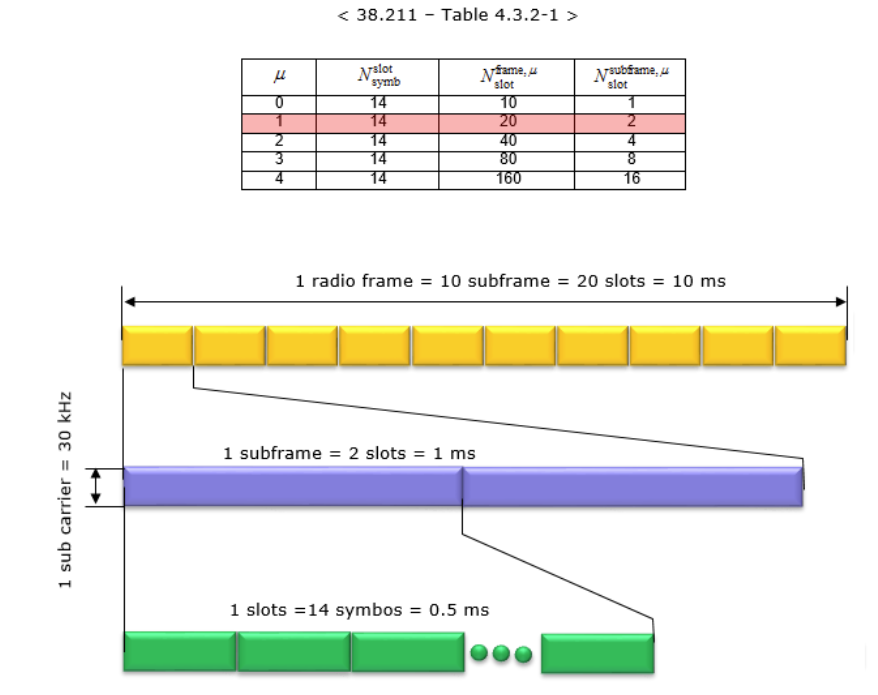

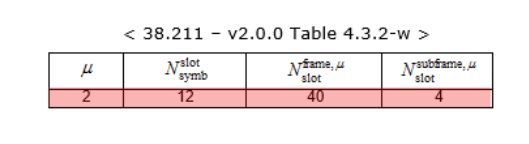

Rate = Pkt_size/(T_slot*(10^(-3)))

Rate = 2928000

% Define the SCS (Subcarrier Spacing) values in kHz
mu_values = [0, 1, 2];

% Define the bandwidth values in MHz
bandwidth_values = [5, 10, 15, 20, 25, 30, 40, 50, 60, 70, 80, 90, 100];

% Define constants

data_width = 9; % Data width in bits
BFP = true; % Boolean indicating if BFP (Base Frequency Partitioning) is true
PKt_header = 36; % Packet header size in bytes
Radio_frame = 10; % Radio frame size in ms

% Initialize empty arrays to store results
prb_tables = zeros(length(mu_values), length(bandwidth_values));
packet_sizes = zeros(length(mu_values), length(bandwidth_values));
rates = zeros(length(mu_values), length(bandwidth_values));
% Loop through each combination of SCS and bandwidth
for i = 1:length(mu_values)
    for j = 1:length(bandwidth_values)
        SCS = 15 * (2^mu_values(i));
        BW_FR1 = bandwidth_values(j); % Bandwidth in MHz for FR1
        BW_guard = table_data{string(SCS), string(BW_FR1)};
        PRB = floor((BW_FR1 * 1000 - (BW_guard * 2)) / (SCS * 12));
        
        % Calculate PRB size based on BFP
        if BFP
            Prb_size = (data_width * 12 * 2 + 8) / 8; % 9 mantissa bits * 2 (IQ) * 12 subcarriers + 8
        else
            Prb_size = (data_width * 12 * 2) / 8;
        end
        
        % Calculate packet size
        iq_data_size = PRB * Prb_size;
        Pkt_size = iq_data_size + PKt_header;
        
        % Store packet size in the array
        packet_sizes(i, j) = Pkt_size;
        rates(i,j) = (Pkt_size*12*(mu_values(i)+1)*8)*10^(-3);
        prb_tables(i,j) = floor((BW_FR1 * 1000 - (BW_guard * 2)) / (SCS * 12));
    end
end

% Create a table for the packet sizes
packet_size_table = array2table(packet_sizes, 'RowNames', string(SCS_values), 'VariableNames', string(bandwidth_values));
rates_table = array2table(rates, 'RowNames', string(SCS_values), 'VariableNames', string(bandwidth_values));
prb_table = array2table(prb_tables, 'RowNames', string(SCS_values), 'VariableNames', string(bandwidth_values));
% Display the packet size table
disp(packet_size_table);

           5      10      15      20      25      30      40      50      60      70      80      90     100 
          ___    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

    15    736    1492    2248    3004    3760    4516    6084    7596     NaN     NaN     NaN     NaN     NaN
    30    344     708    1100    1464    1856    2220    3004    3760    4572    5328    6112    6896    7680
    60    NaN     344     540     708     904    1100    1464    1

disp(rates_table.*0.8)

            5         10        15        20        25        30        40        50        60        70        80        90       100  
          ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    15    56.525    114.59    172.65    230.71    288.77    346.83    467.25    583.37       NaN       NaN       NaN       NaN       NaN
    30    52.838    108.75    168.96    224.87    285.08    340.99    461.41    577.54    702.26    818.38     9

% writetable(rates_table)
% disp(prb_tabl)

Unrecognized function or variable 'prb_tabl'.